%robot parameters
r = 1.5;
L=3;
R=3.5;

params = [r, L, R];

%variables
x0 = [1, -0.1, 0];
xf = [0, 0.75, 90];
t = linspace(0,2,50)

t =          0    0.0408    0.0816    0.1224    0.1633    0.2041    0.2449    0.2857    0.3265    0.3673    0.4082    0.4490    0.4898    0.5306    0.5714    0.6122    0.6531    0.6939    0.7347    0.7755    0.8163    0.8571    0.8980    0.9388    0.9796    1.0204    1.0612    1.1020    1.1429    1.1837    1.2245    1.2653    1.3061    1.3469    1.3878    1.4286    1.4694    1.5102    1.5510    1.5918    1.6327    1.6735    1.7143    1.7551    1.7959    1.8367    1.8776    1.9184    1.9592    2.0000


n = length(t);
T = t(end);

%xplan
x = x_plan(x0,xf,t)

x =     1.0000    0.9796    0.9592    0.9388    0.9184    0.8980    0.8776    0.8571    0.8367    0.8163    0.7959    0.7755    0.7551    0.7347    0.7143    0.6939    0.6735    0.6531    0.6327    0.6122    0.5918    0.5714    0.5510    0.5306    0.5102    0.4898    0.4694    0.4490    0.4286    0.4082    0.3878    0.3673    0.3469    0.3265    0.3061    0.2857    0.2653    0.2449    0.2245    0.2041    0.1837    0.1633    0.1429    0.1224    0.1020    0.0816    0.0612    0.0408    0.0204         0
   -0.1000   -0.0827   -0.0653   -0.0480   -0.0306   -0.0133    0.0041    0.0214    0.0388    0.0561    0.0735    0.0908    0.1082    0.1255    0.1429    0.1602    0.1776    0.1949    0.2122    0.2296    0.2469    0.2643    0.2816    0.2990    0.3163    0.3337    0.3510    0.3684    0.3857    0.4031    0.4204    0.4378    0.4551    0.4724    0.4898    0.5071    0.5245    0.5418    0.5592    0.5765    0.5939    0.6112    0.6286    0.6459    0.6633    0.6806    0.6980    0.7153    0.7327    0

%inv kin
q = inv_kin(x, t, params);

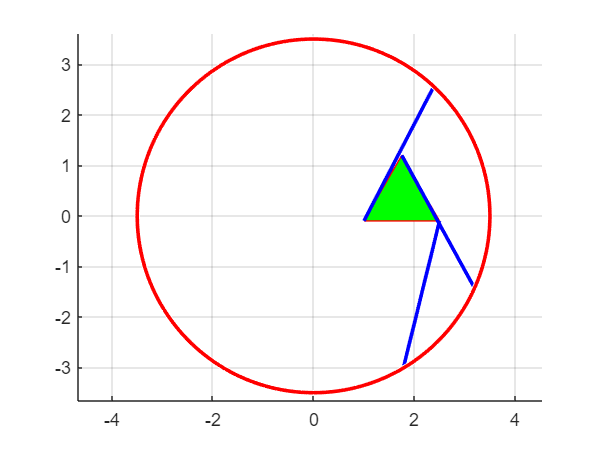

%drawing
x1 = x0(1); x2 = x0(1)+r*cos(x0(3)); x3 = x0(1)+r*cos(x0(3)+deg2rad(60));
y1 = x0(2); y2 = x0(2)+r*sin(x0(3)); y3 = x0(2)+r*sin(x0(3)+deg2rad(60));


figure
hold on;
patch([x1 x2 x3], [y1 y2 y3], 'green', 'edgecolor', 'red')
plot([x1 R*cos(q(3,1)) ], [y1 R*sin(q(3,1)) ], 'blue', 'linewidth', 2);
plot([R*cos(q(5,1)) x1+r*cos(x0(3))],[R*sin(q(5,1)) y1+r*sin(x0(3))], 'blue', 'linewidth', 2);
plot([R*cos(q(1,1)) x1+r*cos(pi/3+x0(3))],[R*sin(q(1,1)) y1+r*sin(pi/3+x0(3))], 'blue', 'linewidth', 2);

viscircles([0,0],R);
grid on
axis equal

xlim([-4.67 4.54])
ylim([-3.65 3.61])

figure
for i=1:n
    x1 = x(1,i); x2 = x(1,i)+r*cos(x(3,i)); x3 = x(1,i)+r*cos(x(3,i)+deg2rad(60));
    y1 = x(2,i); y2 = x(2,i)+r*sin(x(3,i)); y3 = x(2,i)+r*sin(x(3,i)+deg2rad(60));
    hold on;
    p1 = patch([x1 x2 x3], [y1 y2 y3], 'green', 'edgecolor', 'red');
    p2 = plot([x1 R*cos(q(3,i)) ], [y1 R*sin(q(3,i)) ], 'blue', 'linewidth', 2);
    p3 = plot([R*cos(q(5,i)) x1+r*cos(x(3,i))],[R*sin(q(5,i)) y1+r*sin(x(3,i))], 'blue', 'linewidth', 2);
    p4 = plot([R*cos(q(1,i)) x1+r*cos(pi/3+x(3,i))],[R*sin(q(1,i)) y1+r*sin(pi/3+x(3,i))], 'blue', 'linewidth', 2);
    hold off;
    viscircles([0,0],R);
    grid on
    axis equal
    pause(T/n);
    xlim([-4.67 4.54])
    ylim([-3.65 3.61])
    grid on
    xlabel('x')
    ylabel('y')
    title = ['visualization of trajectory'];
    a(i) = norm([x1  y1] - [R*cos(q(3,i)) R*sin(q(3,i)) ]);
    b(i) = norm([R*cos(q(5,i)) R*sin(q(5,i))] - [x1+r*cos(x(3,i)) y1+r*sin(x(3,i))]);
    c(i) = norm([R*cos(q(1,i)) R*sin(q(1,i))] - [x1+r*cos(pi/3+x(3,i)) y1+r*sin(pi/3+x(3,i))]);
    delete(p1);delete(p2);delete(p3);delete(p4);
end

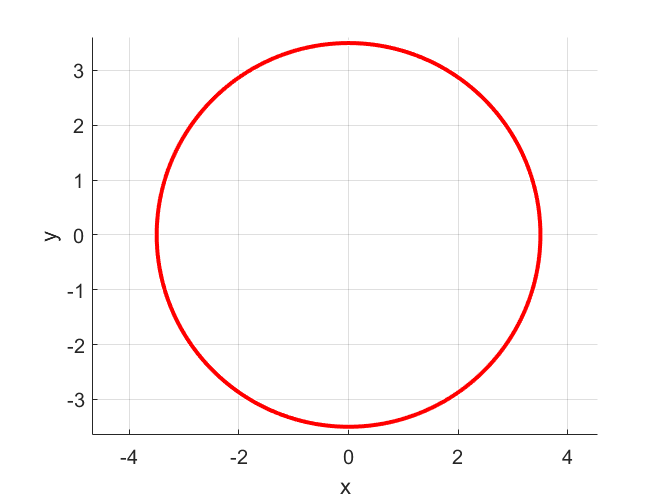

hold off;

a

a =     3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000


b

b =     3.0001    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    2.9999    3.0001    3.0001    3.0000    3.0001    3.0001    3.0000    3.0000    3.0001    2.9999    2.9999    2.9999    3.0000    3.0001    3.0000    3.0000    2.9999    3.0000    3.0000    3.0000    3.0000    2.9999    2.9999    3.0000    3.0000    3.0000    3.0000    3.0000    3.0001    2.9999    3.0000    3.0000    2.9999    3.0001    3.0001    2.9999    3.0000    2.9999    3.0001    3.0001    2.9999    3.0000


c

c =     3.0000    2.9999    3.0001    3.0000    2.9999    3.0001    3.0001    2.9999    2.9999    3.0000    2.9999    3.0001    2.9999    2.9999    3.0000    3.0001    3.0000    3.0000    3.0001    3.0000    3.0000    3.0001    3.0000    3.0000    3.0000    3.0000    3.0000    3.0001    3.0000    3.0000    2.9999    3.0000    3.0001    3.0001    3.0000    3.0000    3.0000    2.9999    3.0001    3.0000    3.0000    3.0000    3.0000    3.0001    3.0000    2.9999    3.0000    3.0000    3.0001    3.0000


q

q =    1.6224 + 0.0000i   1.6565 + 0.0000i   1.6911 - 0.0000i   1.7260 + 0.0000i   1.7613 + 0.0000i   1.7971 + 0.0000i   1.8332 + 0.0000i   1.8696 + 0.0000i   1.9064 + 0.0000i   1.9436 + 0.0000i   1.9810 + 0.0000i   2.0188 + 0.0000i   2.0567 + 0.0000i   2.0949 + 0.0000i   2.1333 + 0.0000i   2.1719 + 0.0000i   2.2105 + 0.0000i   2.2492 + 0.0000i   2.2880 - 0.0000i   2.3267 + 0.0000i   2.3654 + 0.0000i   2.4040 + 0.0000i   2.4424 + 0.0000i   2.4806 + 0.0000i   2.5186 + 0.0000i   2.5563 + 0.0000i   2.5937 + 0.0000i   2.6308 + 0.0000i   2.6674 + 0.0000i   2.7036 + 0.0000i   2.7393 + 0.0000i   2.7746 + 0.0000i   2.8094 - 0.0000i   2.8436 + 0.0000i   2.8772 + 0.0000i   2.9103 - 0.0000i   2.9428 + 0.0000i   2.9747 - 0.0000i   3.0061 + 0.0000i   3.0368 + 0.0000i   3.0669 - 0.0000i   3.0964 + 0.0000i   3.1253 + 0.0000i  -3.1295 + 0.0000i  -3.1018 - 0.0000i  -3.0747 + 0.0000i  -3.0481 + 0.0000i  -3.0221 - 0.0000i  -2.9966 + 0.0000i   1.2576 + 0.0000i
  -0.4210 + 0.0000i  -0.3893 + 0.0000i  -0.35